## 1) Correlazione ponderata

Il file regioni.xlsx contiene per ciascuna regione Italiana    

TassoPassaggio=Tasso di passaggio all'Università: immatricolati per 100 diplomati di scuola secondaria di secondo grado dell'anno scolastico precedente;

TassoIscrizione=Tasso di iscrizione all'Università: iscritti all'Università (in qualunque sede) residenti in una certa regione per 100 giovani di 19-25 anni residenti nella stessa regione;

 IscrittiFuoriRegione=Iscritti in sedi universitarie ubicate fuori dalla regione di residenza per 100 iscritti (sono esclusi i cittadini stranieri e gli italiani residenti all'estero);

Residenti=Popolazione residente.

Osservazione: I primi tre indicatori possono ritenersi aspetti diversi della  propensione agli studi universitari in ciascuna regione d'Italia, per cui risulta interessante misurare la relazione esistente tra essi, tramite il calcolo del coeffiente di correlazione lineare. Dato che siamo in presenza di una seria territoriale multipla, appare ragionevole nel calcolo dei diversi indici statistici tenere conto della differente importanza delle regioni.

Mostrare tramite GUI tutti i passaggi necessari per calcolare la correlazione tra le variabili TassoPassaggio  e TassoIscrizione. 

Calcolare la matrice dei coefficienti di correlazione nei 3 diversi modi che seguono:

- Tramite la matrice di varianze e covarianze (v. equazione 6.9 del testo).

- Tramite la matrice degli scostamenti standardizzati. Verificare che le medie e le varianze (oppure le std) delle colonne della matrice Z sono 0 e 1.

- Tramite doppio ciclo for.

Testare l'ipotesi che il vero coefficiente di correlazione sia uguale a 0 nell'universo per ogni coppia di variabili. Calcolare i p-values del test. Mostrare la matrice di correlazione e dei p-values del test di assenza di correlazione in formato table. Commentare i risultati ottenuti

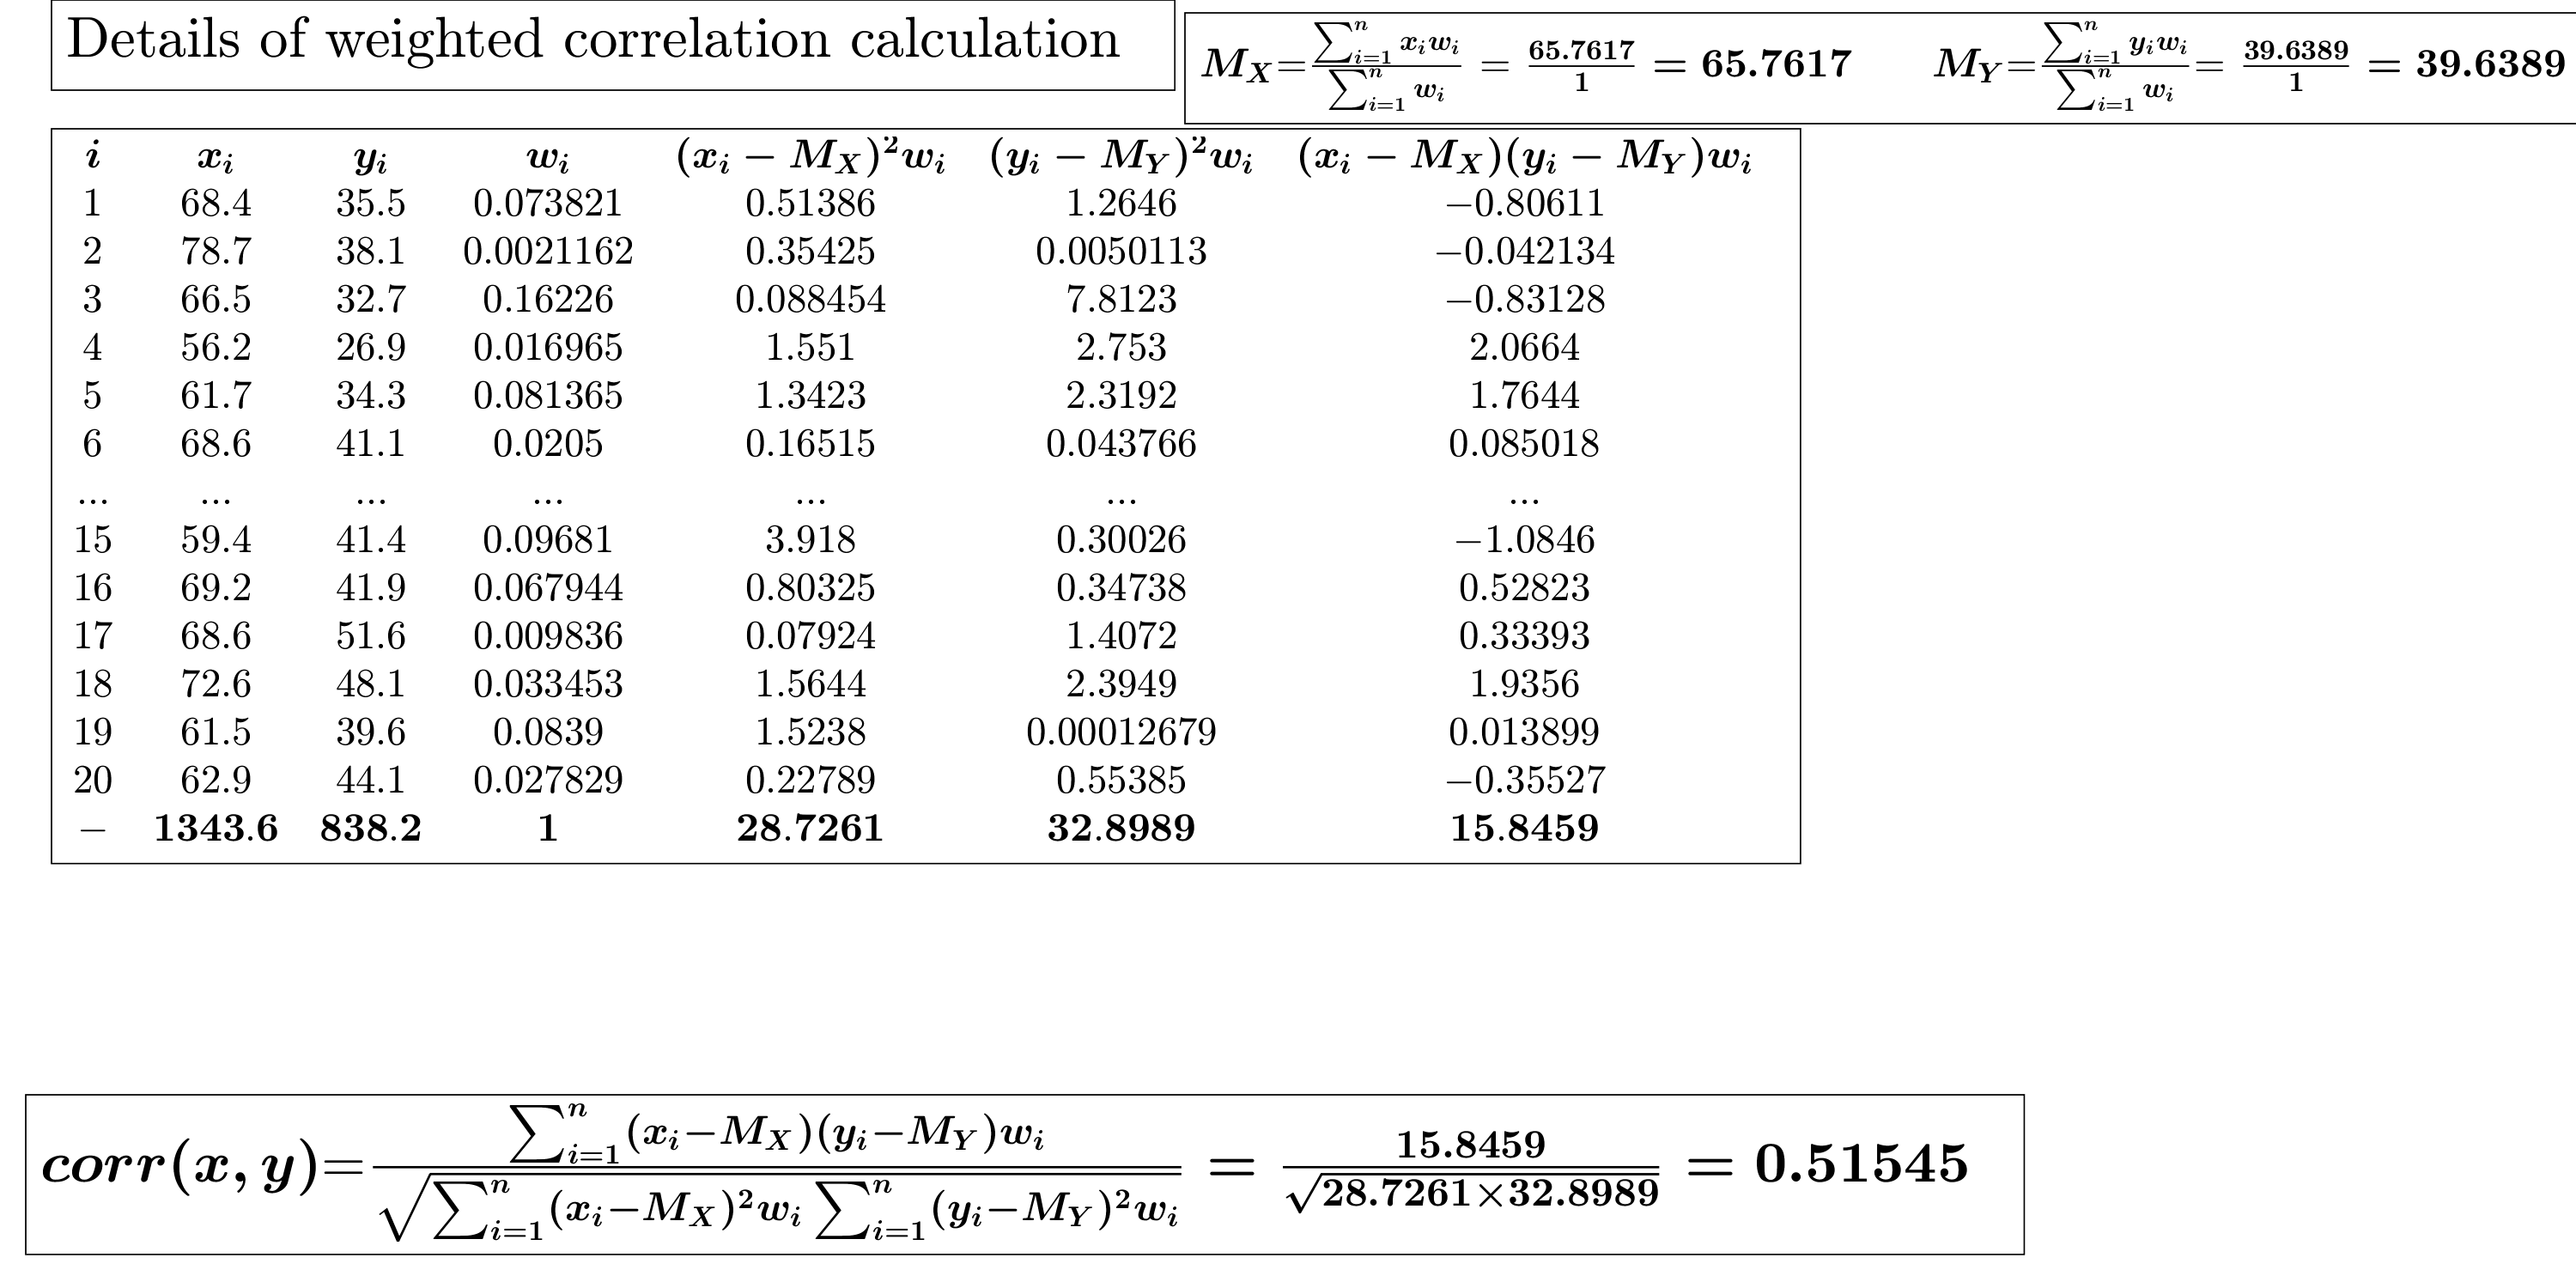

Xtable=readtable("regioni.xlsx",'ReadRowNames',true);
Xd=Xtable{:,1:3};
% Estraggo il vettore dei pesi. Le statistiche devono essere ponderate in
% quanto le regioni hanno una diversa importanza. In questo esempio
% utilizziamo i residenti come variabile peso.
w=Xtable.Residenti;
% Dividere per sum(w) non è necessario in quanto la correlazione è invariante per
% trasformazioni lineari crescenti. Tuttavia lo faccio per convenienza
% computazioanale in modo tale da evitare ogni volta di dividere per la
% somma dei pesi (dato che la somma dei wstar è 1).
wstar=w/sum(w);
% Viene invocata la funzione GUIcorr per mostrare i passaggi relativi al
% calcolo del coefficiente di correlazione ponderato.
out=GUIcorr(Xtable.TassoPassaggio,Xtable.TassoIscrizione,wstar);

% n= numero di osservazioni
% p =numero di variabili
[n,p]=size(Xd);

% Calcolo le medie ponderate
% Osservazione: la somma dei pesi è 1 di conseguenza non è necessario
% dividere per la somma dei pesi
mediePonderate=Xd'*wstar;
% Xtilde= Matrice degli scostamenti dalla media
% La media ponderata di ogni colonna della matrice Xtilde è 0
Xtilde=Xd-mediePonderate';

% sqwstar = vettore colonna di lunghezza n che contiene le radici quadrate
% dei pesi associati ad ogni regione
sqwstar=sqrt(wstar);

% S= matrice di varianze e covarianze, ottenuta tramite
% moltiplicazioni matriciali
XtildePesata=(Xd-mediePonderate').*sqwstar;
S=XtildePesata'*XtildePesata;
% stdX= vettore riga di lunghezza p (dove p è il numero di variabili)
% che contiene le standard deviation (pesate)
stdX=sqrt(diag(S)');

% D = matrice diagonale che contiene sulla diagonale principale le standard
% deviation (pesate) delle p variabili originarie
D=diag(stdX);
% Dalla matrice di covarianze ottengo la matrice di correlazione
% Vedi equazione (6.9) del testo data science con MATLAB (formula
% matriciale per passare dalla matrice di covarianze alla matrice di
% correlazione)
R=D^-1*S*D^-1;
disp("Matrice di correlazione passando attraverso la matrice di covarianze")

Matrice di correlazione passando attraverso la matrice di covarianze


disp(R)

    1.0000    0.5155    0.0782
    0.5155    1.0000    0.2343
    0.0782    0.2343    1.0000




% Z matrice degli scostamenti standardizzati ponderata
% La media ponderata di ogni colonna è 0 e la varianza ponderata di ogni
% colonna della matrice Z è 1.
Z=Xtilde./stdX;

% Verifico che la media ponderata di ogni colonna è 0 e che la varianza
% ponderata di ogni colonna della matrice Z è 1.
medieZ=Z'*wstar;
tol=10^-13;
assert(max(abs(medieZ))<tol,"ERRORE: le medie ponderate delle colonne della matrice Z non sono 0")
stdZ=std(Z,wstar);
assert(max(abs(stdZ-1))<tol,"ERRORE: le varianze ponderate delle colonne della matrice Z non sono 1")

Zpesata=Z.*sqwstar;
% L'espressione Zpesata'*Zpesata non è altro che la generalizzazione matriciale
% dell'equazione (7.13) dell'immagine di seguito
Rchk=Zpesata'*Zpesata;
% Un modo alternativo (inefficiente) per calcolare la matrice di
% correlazione era Z'*diag(wstar)*Z
disp("Matrice di correlazione passando attraverso la matrice Z")

Matrice di correlazione passando attraverso la matrice Z


disp(Rchk)

    1.0000    0.5155    0.0782
    0.5155    1.0000    0.2343
    0.0782    0.2343    1.0000



OSSERVAZIONE: questo esercizio è stato estratto dalle pagine 238-239 del libro di Statistica Introduzione all'analisi dei dati statistici (2019) Milioli, Riani e Zani, Pitagore Editore, 

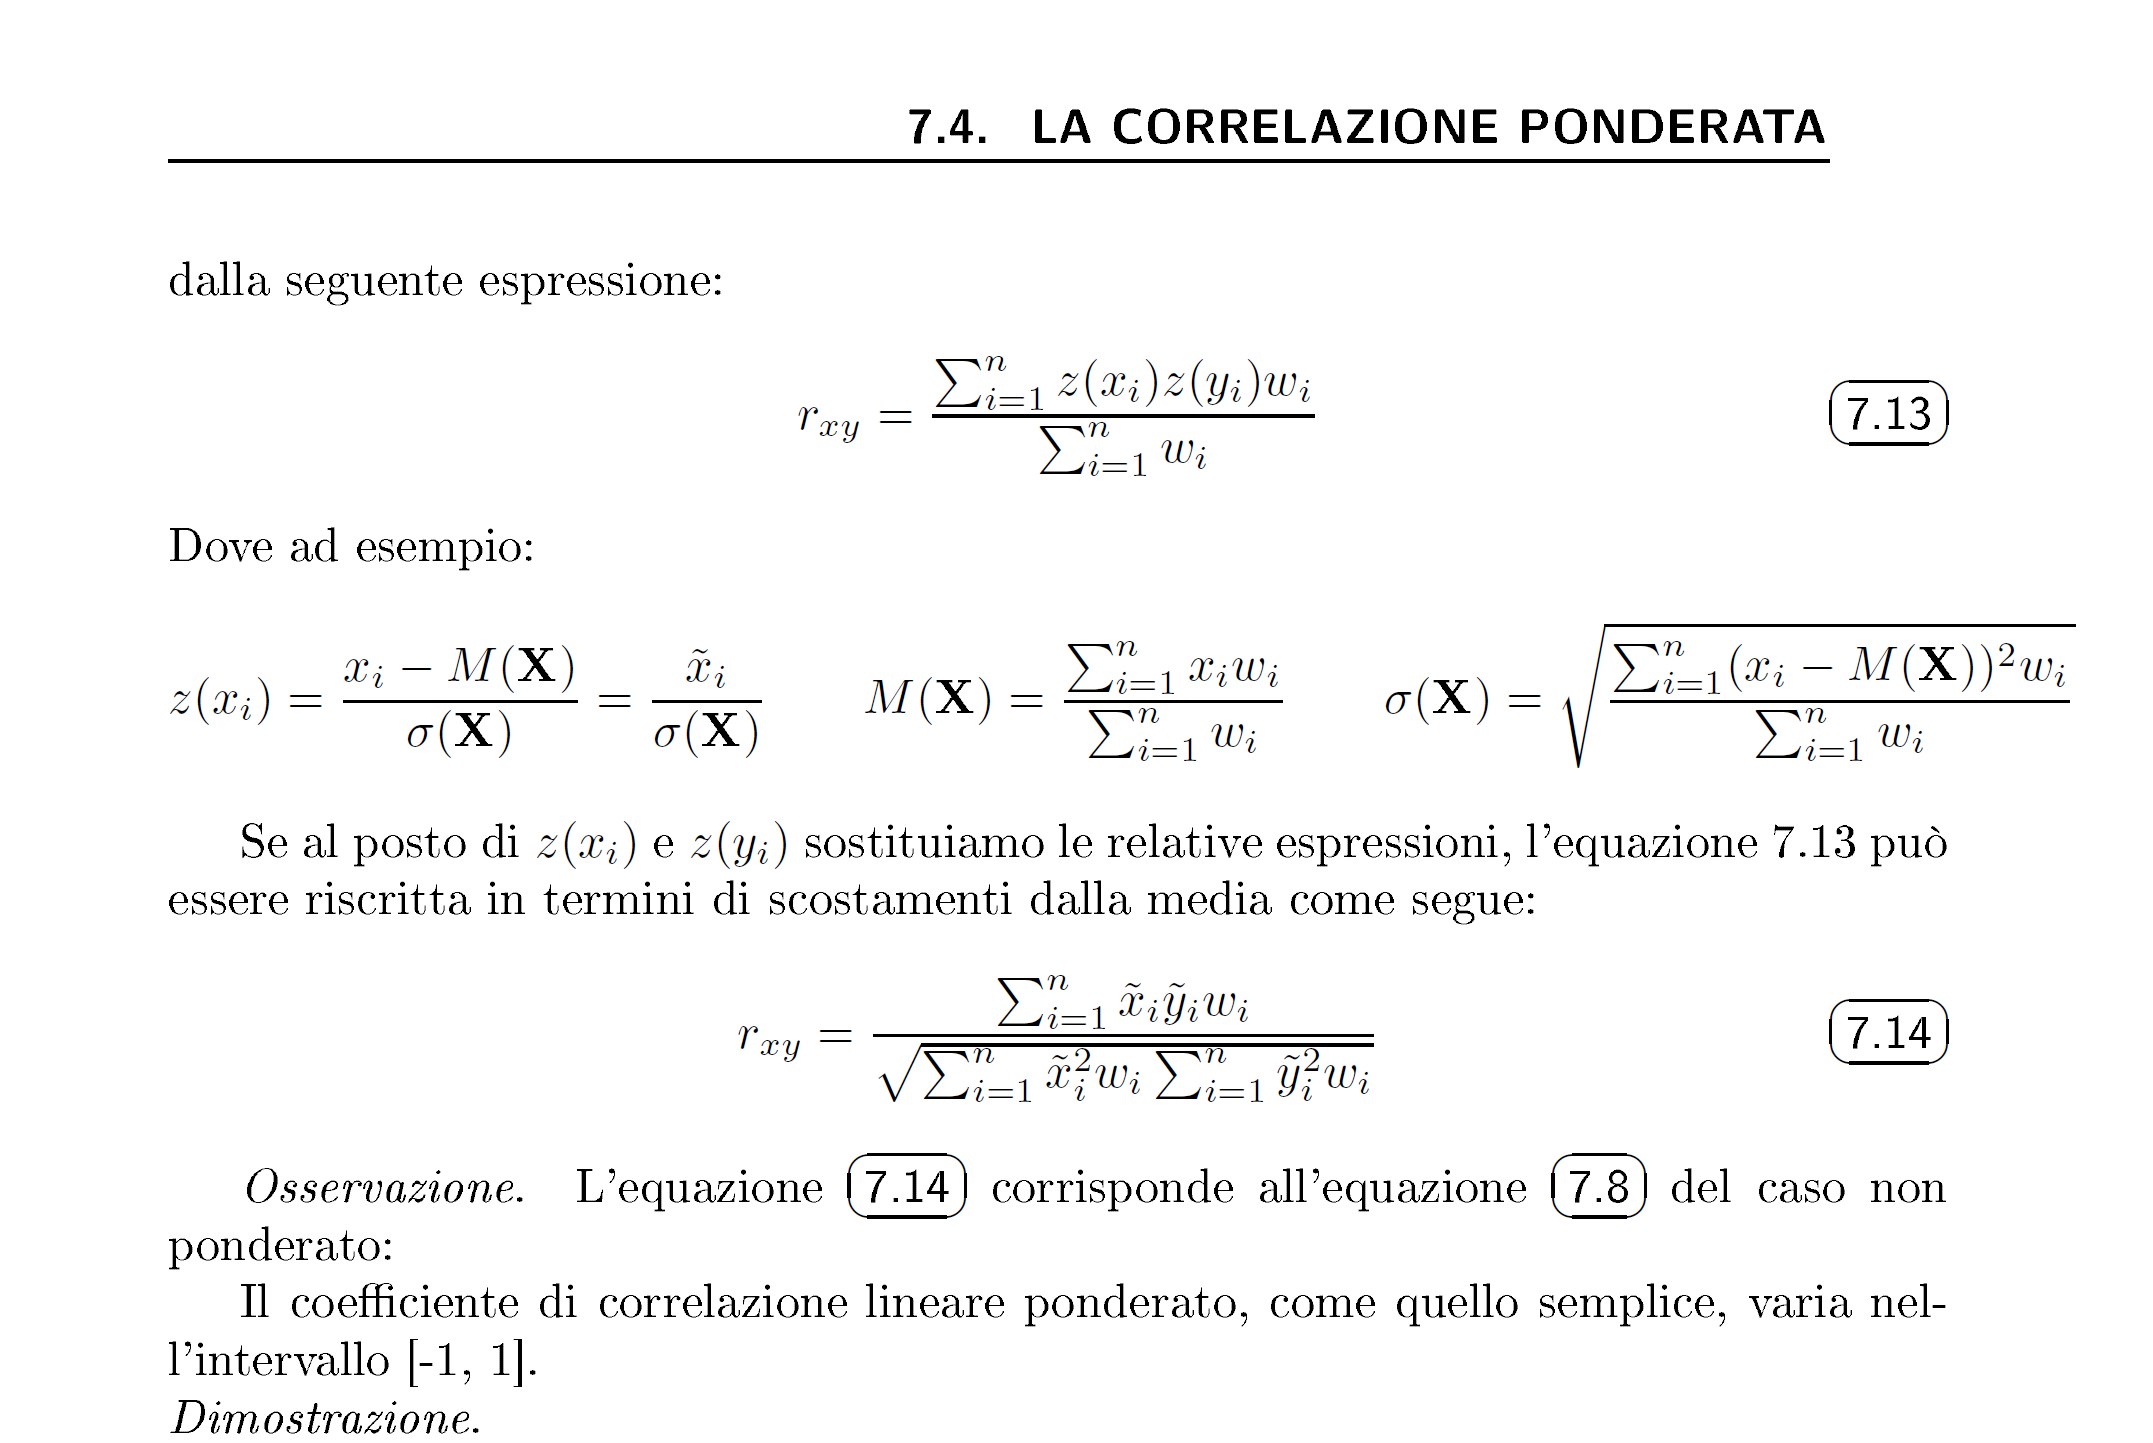

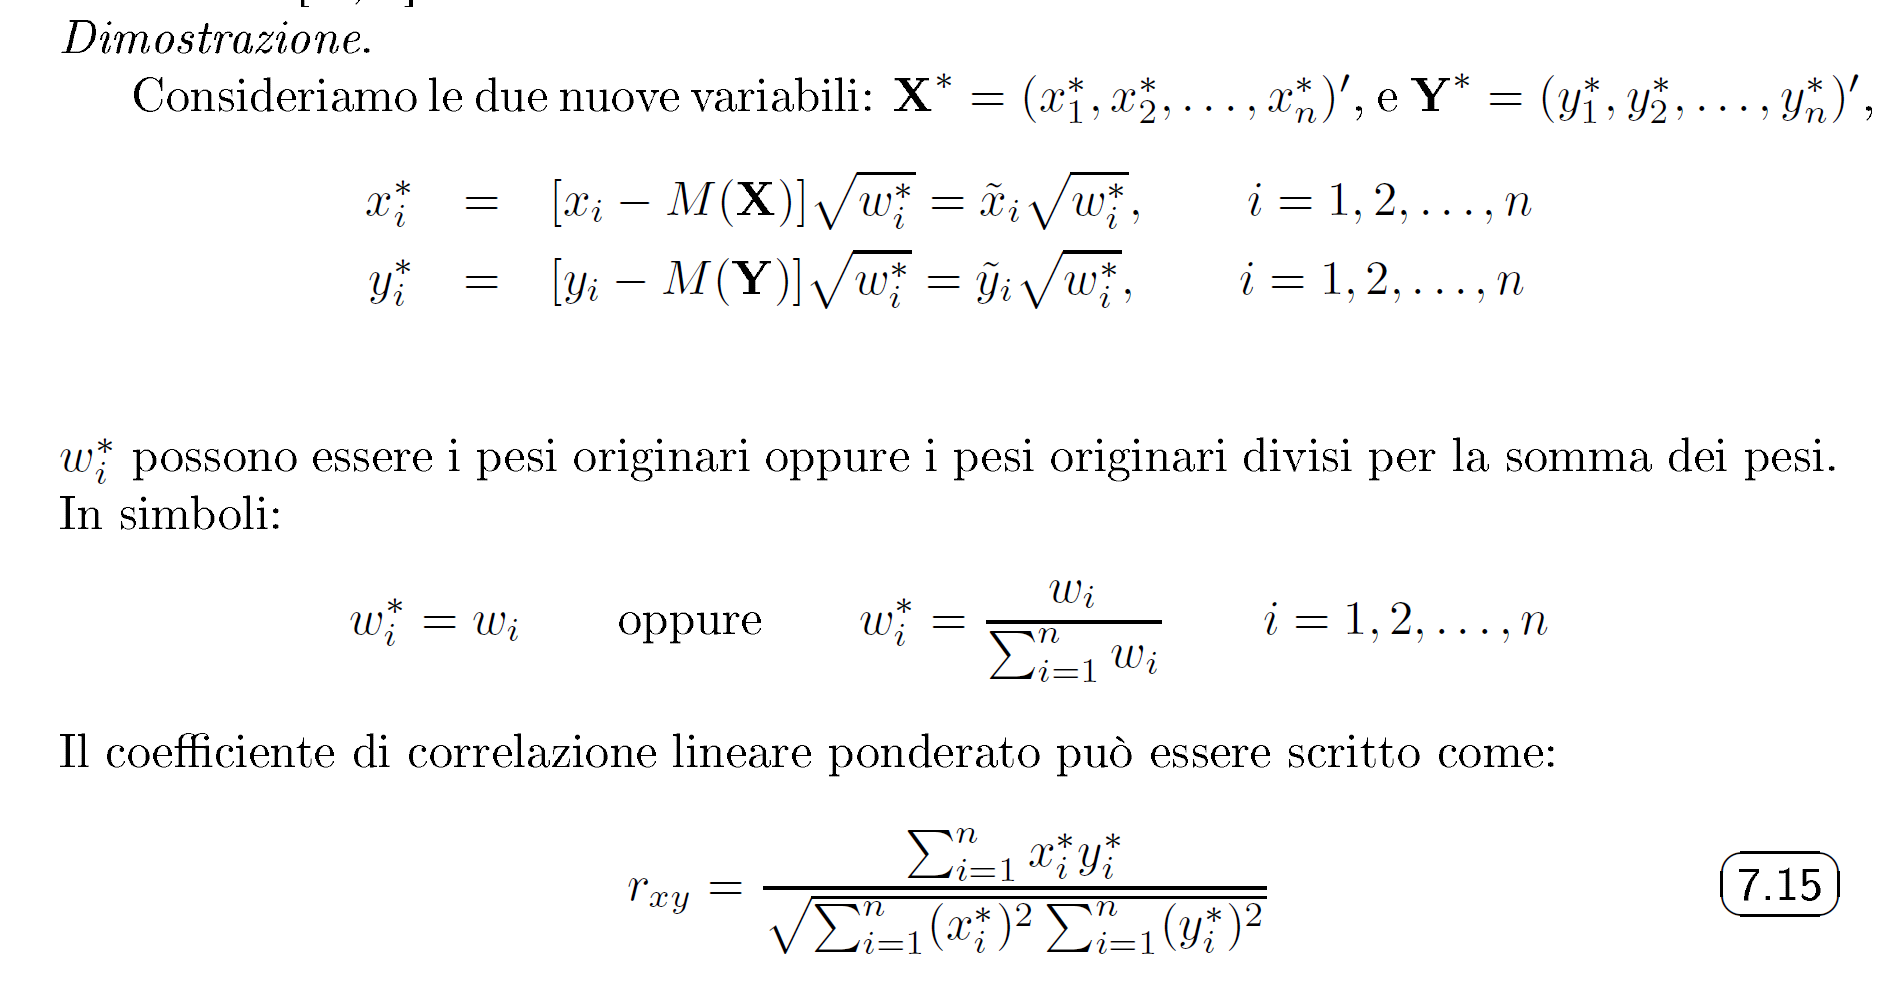

% Di seguito l'implementazione da pivelli tramite cicli for.
% Inizializzo la matrice di correlazione che conterrà i coefficienti di
% correlazione lineare (ponderati)
RdaPivelli=zeros(p,p);
for i=1:p
    % La riga che segue dipende solo dall'indice i e non da j di conseguenza
    % non è efficiente farla ricalcolare ogni volta per ogni j
    xstar=(Xd(:,i)-mediePonderate(i)).*sqwstar;
    for j=1:p
        ystar=(Xd(:,j)-mediePonderate(j)).*sqwstar;
        % Equazione (7.15) dell'immagine sopra applicata all'elemento i,j
        % della matrice di correlazione
        RdaPivelli(i,j)=sum(xstar.*ystar)/sqrt(sum(xstar.^2)*sum(ystar.^2));
        % Ovviamente quando i=j RdaPivelli(i,j)=1
    end
end
disp("Matrice di correlazione tramite implementazione da pivelli")

Matrice di correlazione tramite implementazione da pivelli


disp(RdaPivelli)

    1.0000    0.5155    0.0782
    0.5155    1.0000    0.2343
    0.0782    0.2343    1.0000



% Controllo l'uguaglianza delle diverse implementazioni
tol=1e-12;
AffermazioneDaTestare=max(R-Rchk,[],"all")<tol && max(R-RdaPivelli,[],"all")<tol;
assert(AffermazioneDaTestare,"Le implementazioni sono diverse")

% Calcolo del test di assenza di correlazione per ogni coppia di variabili
Testt=(R./sqrt(1-R.^2))*sqrt(n-2);

% Calcolo dei relativi p-values
Pval=tcdf(abs(Testt),n-2,'upper')*2;
% Aggiungo i valori 1 sulla diagonale principale nella matrice Pval
Pval=Pval +eye(p);

% Dagli array costruisco le table
nam=Xtable.Properties.VariableNames(1:3);
Pvalt=array2table(Pval,"RowNames",nam,"VariableNames",nam);
Rt=array2table(R,"RowNames",nam,"VariableNames",nam);
disp('Matrice di correlazione')

Matrice di correlazione


disp(Rt)

                            TassoPassaggio    TassoIscrizione    IscrittiFuoriRegione
                            ______________    _______________    ____________________

    TassoPassaggio                    1           0.51545              0.078173      
    TassoIscrizione             0.51545                 1               0.23428      
    IscrittiFuoriRegione       0.078173           0.23428                     1      



disp('Matrice dei p-values dei test di assenza di correlazione')

Matrice dei p-values dei test di assenza di correlazione


disp(Pvalt)

                            TassoPassaggio    TassoIscrizione    IscrittiFuoriRegione
                            ______________    _______________    ____________________

    TassoPassaggio                    1          0.020015              0.74322       
    TassoIscrizione            0.020015                 1              0.32013       
    IscrittiFuoriRegione        0.74322           0.32013                    1       



% La relazione lineare tra TassoPassaggio e IscrittiFuoriRegioni non è
% significativa. Stessa cosa dicasi per la coppia di variabili
% IscrittiFuoriRegione e TassoIscrizione. La relazione tra TassoPassaggio e
% TassoIscrizione, al contrario, al livello di significativià del 5 per
% cento è significativa.

## 2) Matrice di correlazione

Caricare in memoria il file head.mat di FSDA toolbox. Per la descrizione di questo dataset si veda l'Esercizio 8.5 del testo oppure la pagina [Flexible Statistics and Data Analysis Toolbox Functions - - By Category (unipr.it)](http://rosa.unipr.it/FSDA/datasets_mv.html). Calcolare e commentare la matrice di correlazione delle 6 variabili. 

Verificare l'ipotesi di assenza di correlazione per ogni coppia di variabili. Calcolare e commentare i relativi p-values. Mostare la matrici di correlazione e quella dei relativi p-values in formato table. Utilizzare come nomi delle variabili nelle due tables la parola che segue l'ultimo underscore. Ad esempio, se nella table originaria head una variabile si chiama length_tragion_nasion si deve estrarre la parola nasion. Mostrare l'output utilizzando solo due cifre decimali.

clear % cancella tutte le variabili presenti in memoria
%% Caricamento della table head in memoria
load head
% X = dataset in formato double (solo numeri)
X=head{:,:};
% Costruzione della matrice di correlazione e dei relativi p-values
[R,Pval]=corr(X);
% nomivar è definito come vettore colonna
nomivar=head.Properties.VariableNames';
% Viene utilizzata la funzione split per separare le parole contenute nel
% cell array nomivar
nomiSeparati=split(nomivar,'_');
% Le parole che seguono l'ultimo underscore (contenute nella colonna 3
% di nomiSeparati) viene assegnati alla variabile denominata nominuovi
nominuovi=nomiSeparati(:,3);

PvalT=array2table(Pval,"RowNames",nominuovi,"VariableNames",nominuovi);
RT=array2table(R,"RowNames",nominuovi,"VariableNames",nominuovi);

% Imposto il formato con solo due cifre decimali (vedi sezione 1.8.3 del
% testo)
format bank
disp(RT)

                  breadth    mandibulae    height    nasi    nasion    gnathion
                  _______    __________    ______    ____    ______    ________

    breadth        1.00         0.47        0.17     0.13     0.40       0.41  
    mandibulae     0.47         1.00        0.09     0.09     0.35       0.39  
    height         0.17         0.09        1.00     0.41     0.26       0.24  
    nasi           0.13         0.09        0.41     1.00     0.18       0.21  
    nasion         0.40         0.35        0.26     0.18     1.00       0.66  
    gnathion       0.41         0.39        0.24     0.21     0.66       1.00  



disp(PvalT)

                  breadth    mandibulae    height    nasi    nasion    gnathion
                  _______    __________    ______    ____    ______    ________

    breadth        1.00         0.00        0.01     0.06     0.00       0.00  
    mandibulae     0.00         1.00        0.19     0.19     0.00       0.00  
    height         0.01         0.19        1.00     0.00     0.00       0.00  
    nasi           0.06         0.19        0.00     1.00     0.01       0.00  
    nasion         0.00         0.00        0.00     0.01     1.00       0.00  
    gnathion       0.00         0.00        0.00     0.00     0.00       1.00  




% Tutti i coefficienti di correlazione lineare sono positivi.
% Quasi tutte le correlazioni risultano significative.  Questo significa
% che ad una faccia con valori (ad esempio) elevati della lunghezza della
% mandibola (mandibulae), corrispondono elevati di (ad esempio) lunghezza del naso. Alle
% facce più larghe (breadth) corrisponono altezze facciali (height) più
% elevate...


## 3) Il significato del *p*-value

In un campione bivariato composto da 7 osservazioni è stato trovato un valore del coefficiente di correlazione lineare uguale -0.65. Se le due variabili sono incorralte nell'universo, qual è la probabilità di ottenere nel campione un valore in modulo superiore a 0.65? Calcolare questa probabilità prima teoricamente e poi empiricamente andando ad estrarre 10000 campioni dalla distribuzione normale bivariata con parametro rho=0. 

% il test riportato nell'equazione (6.10) del testo si distribuisce come una
% v.c T di Student con n-2 gradi di libertà.
% Calcolo del test tr
n=7;
r=-0.65;
tr=(r./sqrt(1-r.^2))*sqrt(n-2);

% Calcolo del p-value del test
% Moltiplico l'area della coda di destra per 2 poiché l'ipotesi alternativa
% è bilaterale
pval=tcdf(abs(tr),n-2,'upper')*2;
% absr= valore assoluto di r campionario in formato character
absr=num2str(abs(r));

disp(['La probabilità di ottenere un valore di r superiore a ' absr ' oppure inferiore a -' absr])

La probabilità di ottenere un valore di r superiore a 0.65 oppure inferiore a -0.65


disp(['è uguale a ' num2str(pval) ' se il campione di numerosità n=' num2str(n)])

è uguale a 0.11401 se il campione di numerosità n=7


disp('è stato estratto da una distribuzione normale bivariata con rho=0')

è stato estratto da una distribuzione normale bivariata con rho=0


% Verifico questa probabilità empiricamente.

nsimul=10000;
% I valori di mux, sigmax, muy, sigmay sono fissati a caso. Il risultato
% non dipende dai valori di questi 4 parametri
mux=123;
sigmax=456;
muy=6780;
sigmay=27934;

Rall=zeros(nsimul,1);
for i=1:nsimul
    % Per ogni simulazione vengono generati due vettori indipendenti di
    % dimensione nx1 dalla distribuzione normale univariata
    % Osservazione: questo equivale a generare da una distribuzione normale
    % bivariata con parametro rho=0
    x=normrnd(mux,sigmax,n,1);
    y=normrnd(muy,sigmay,n,1);
    % Per ogni simulazione si calcola il coefficiente di correlazione
    % lineare
    % Inserisco il valore del coefficiente di correlazione per la
    % simulazione i nella riga i del vettore Rall
    Rall(i)=corr(x,y);
end
probEmpirica=sum(abs(Rall)>r)/nsimul;

disp(['La probabilità empirica risulta uguale a ' num2str(probEmpirica)])

La probabilità empirica risulta uguale a 1


% Si noti che la probabilità empirica è molto vicina a quella teorica.
% All'aumentare di nsimul la probabilità empirica tende a quella teorica


## 4) La distribuzione campionaria del coefficiente di correlazione quando rho è diverso da zero

La distribuzione del coefficiente di correlazione campionario quando i dati provengono da una distribuzione normale bivariata con coefficiente di correlazione lineare nell'universo (parametro rho $\rho$)  diverso da zero [è la seguente](https://mathworld.wolfram.com/CorrelationCoefficientBivariateNormalDistribution.html):


$$f(r|\rho, n) =\frac{(n-2) \Gamma(n-1)\left(1-\rho^2\right)^{(n-1) / 2}\left(1-r^2\right)^{(n-4) / 2}}{\sqrt{2 \pi} \Gamma\left(n-\frac{1}{2}\right)(1-\rho r)^{n-3 / 2}} \times\left[1+\frac{1}{4} \frac{\rho r+1}{2 n-1}+\frac{9}{16} \frac{(\rho r+1)^2}{(2 n-1)(2 n+1)}+\cdots\right]$$


dove *n* è il numero di unità statistiche del campione, $\Gamma \;$ è la funzione Gamma (v. sezione 4.3 del testo) *r* è il coefficiente di correlazione campionario e $\rho$ è il coefficiente di correlazione nell'universo. 

Mostrare la densità *f(r)* nell'intervallo [-1, 1] quando $\rho$ = 0.4 e la numerosità campionaria è pari a 7.

Costruire un nuovo grafico in cui alla densità viene sovraimposto il grafico ad istogrammi della distribuzione empirica di *r* basata su 10000 simulazioni. Nel grafico ad istogrammi utilizzare il `'name',value 'Normalization','pdf'`.

Osservazione: la densità precedente può essere implementata manualmente oppure chiamando la funzione `corrpdf` di FSDA toolbox (dalla versione 8.5.38).

Calcolare la probabilità in un campione di 7 osservazioni di ottenere un valore del coefficiente di correlazione campionario superiore a 0.7 quando $\rho$ = 0.4. 

Osservazione: la  probabilità esatta è data da


$$Pr(r>0.7| \rho=0.4, n=7) = \int_{0.7}^1 f(r| \rho=0.4, n=7) dr$$


Osservazione: la funzione di ripartizione della distribuzione campionaria di *r* può essere calcolata utilizzando la funzione `corrcdf`. 

Confrontare la probabilità teorica con quella empirica. 

Osservazione: la probabilità emprica è uguale alla frazione di  volte in nsimul ripetizioni in cui otteniamo un valore del coefficiente di correlazione campionario maggiore di 0.7 in campioni di numerosità n=7 provenienti da una distribuzione normale bivariata con parametro rho=0.4.

Rappresentazione grafica della densità di r quando rho=0.4 e n=7

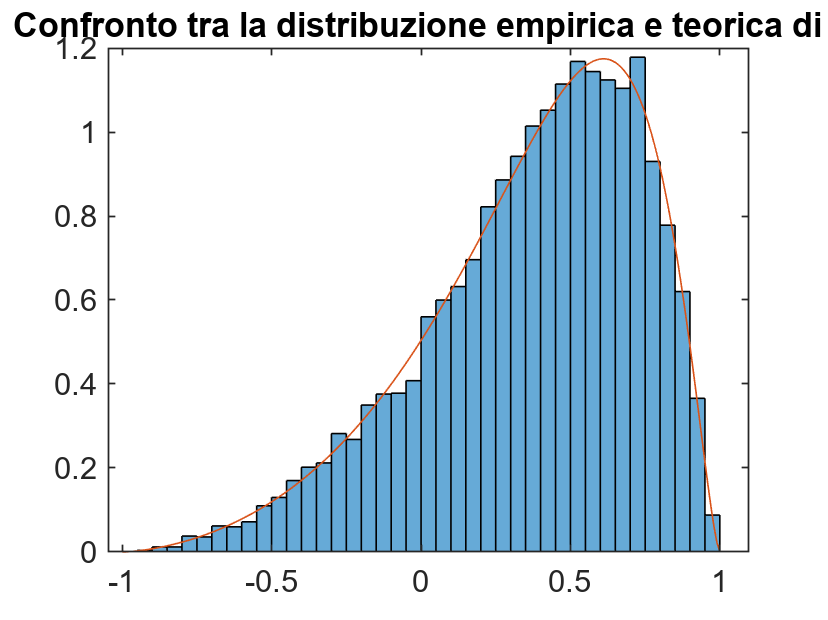

rho=0.4;
% r = vettore che contiene l'insieme delle coordinate per cui deve essere
% calcolata la densità
r=(-1:0.01:1)';
% Calcolo manuale della densità della distribuzione di r
y = (n-2) * gamma(n-1) * (1-rho^2)^((n-1)/2) * (1-r.^2).^((n-4)/2);
y = y./ (sqrt(2*pi) * gamma(n-1/2) * (1-rho*r).^(n-3/2));
y = y.* (1+ 1/4*(rho*r+1)/(2*n-1) + 9/16*(rho*r+1).^2 / (2*n-1)/(2*n+1));
plot(r,y)
xlabel('Coefficiente di correlazione campionario r')
ylabel('Densità di r')
title(['Densità di r quando rho=' num2str(rho) ' e n=' num2str(n)])

% Rall in questo caso conterrà la distribuzione dei valori
% del coefficiente di correlazione lineare campionario nelle nsimul simulazioni
% nel caso in cui il vero valore di rho è 0.4
Rall=zeros(nsimul,1);
% Per ogni simulazione vengono generate n osservazioni da una distribuzione
% normale bivariata con parametro rho=0.4. Il vettore mu (primo input della
% funzione mvnrnd) senza perdita di generalità può essere posto uguale
% [0;0]
Sigma=[1 rho; rho 1];

for i=1:nsimul
    % Per ogni i, il campione viene generato da una distribuzione normale
    % bivariata
    X=mvnrnd([0;0],Sigma,n);
    % Per ogni simulazione si calcola il coefficiente di correlazione
    % lineare.
    % Inserisco il valore del coefficiente di correlazione per la
    % simulazione i nella riga i del vettore Rall
    Rall(i)=corr(X(:,1),X(:,2));
end

% Nuovo grafico in cui agli istogrammi si sovrappone la densità.
% Grafico ad istogrammi della distribuzione del coefficiente di
% correlazione lineare, quando il vero valore nell'universo è pari a
% rho=0.4
figure
histogram(Rall,'Normalization','pdf')
hold("on")
plot(r,y)
title('Confronto tra la distribuzione empirica e teorica di r')

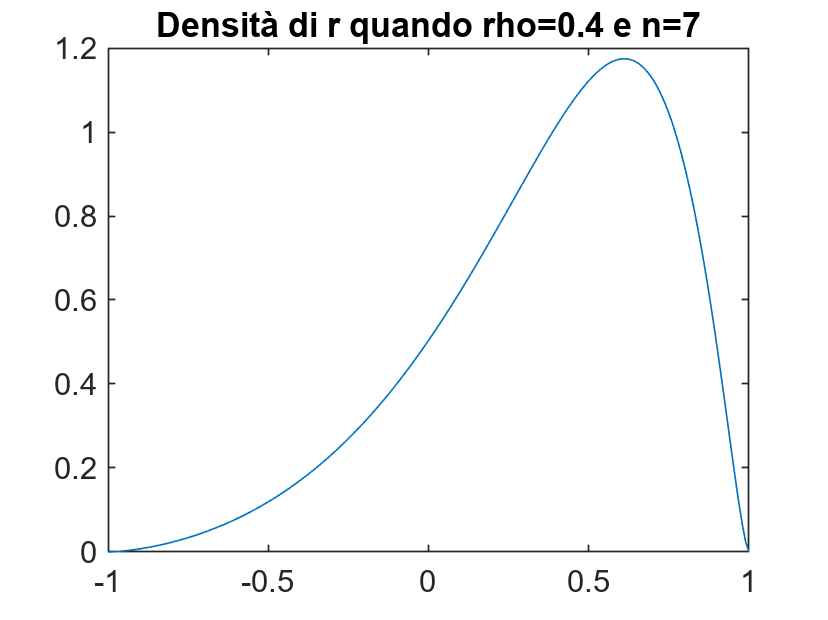

% Commento al grafico precedente: la distribuzione empirica si sovrappone
% perfettamete alla distribuzione teorica. Abbiamo sicuramente verificato
% che quello che è stato dimostrato teoricamente (espressione matematica
% della densità di r) corrisponde a quello che capità nella realtà.

% Calcolo della densità tramite la chiamata alla funzione corrpdf(x,rho,n)
figure
densrho=corrpdf(r,rho,n);
plot(r,densrho)
title(['Densità di r quando rho=' num2str(rho) ' e n=' num2str(n)])

% Calcolo probabilità Pr(r>0.7|rho=0.4, n=7), ossia calcolo della
% probabilità che il coefficiente di correlazione campionario sia maggiore
% di 0.7 quando il vero rho nella popolazione è 0.4 e si estrae un campione
% di 7 elementi

% Calcolo della probabilità esatta tramite l'integrale della densità
% nell'intervallo [0.7 1]. Viene chiamata la funzione corrcdf con il quarto
% argomento di input uguale ad 'upper' in modo tale da calcolare la
% probabilità di valori superiori a 0.7
probTheo=corrcdf(0.7,0.4,7,'upper');
disp(['Calcolo tramite integrale Pr(r>0.7|rho=0.4, n=7)=' num2str(probTheo)])

Calcolo tramite integrale Pr(r>0.7|rho=0.4, n=7)=0.19641



% Calcolo della probabilità tramite la frequenza relativa empirica
ProbEmpirica=sum(Rall>0.7)/nsimul;
disp(['Calcolo empirico Pr(r>0.7|rho=0.4, n=7)=' num2str(ProbEmpirica)])

Calcolo empirico Pr(r>0.7|rho=0.4, n=7)=0.198


% La probabilità teorica è molto vicina a quella empirica.

## 5) Densità di r al variare di rho

Mostrare la funzione di densità del coefficiente di correlazione campionario in corrispondenza dei valori di rho=0, 0.2, 0.4, 0.6, 0.8, 0.9  in 6 pannelli grafici. Inserire un titolo dinamico per ogni pannello ed un titolo globale come riportato nell'immagine che segue 

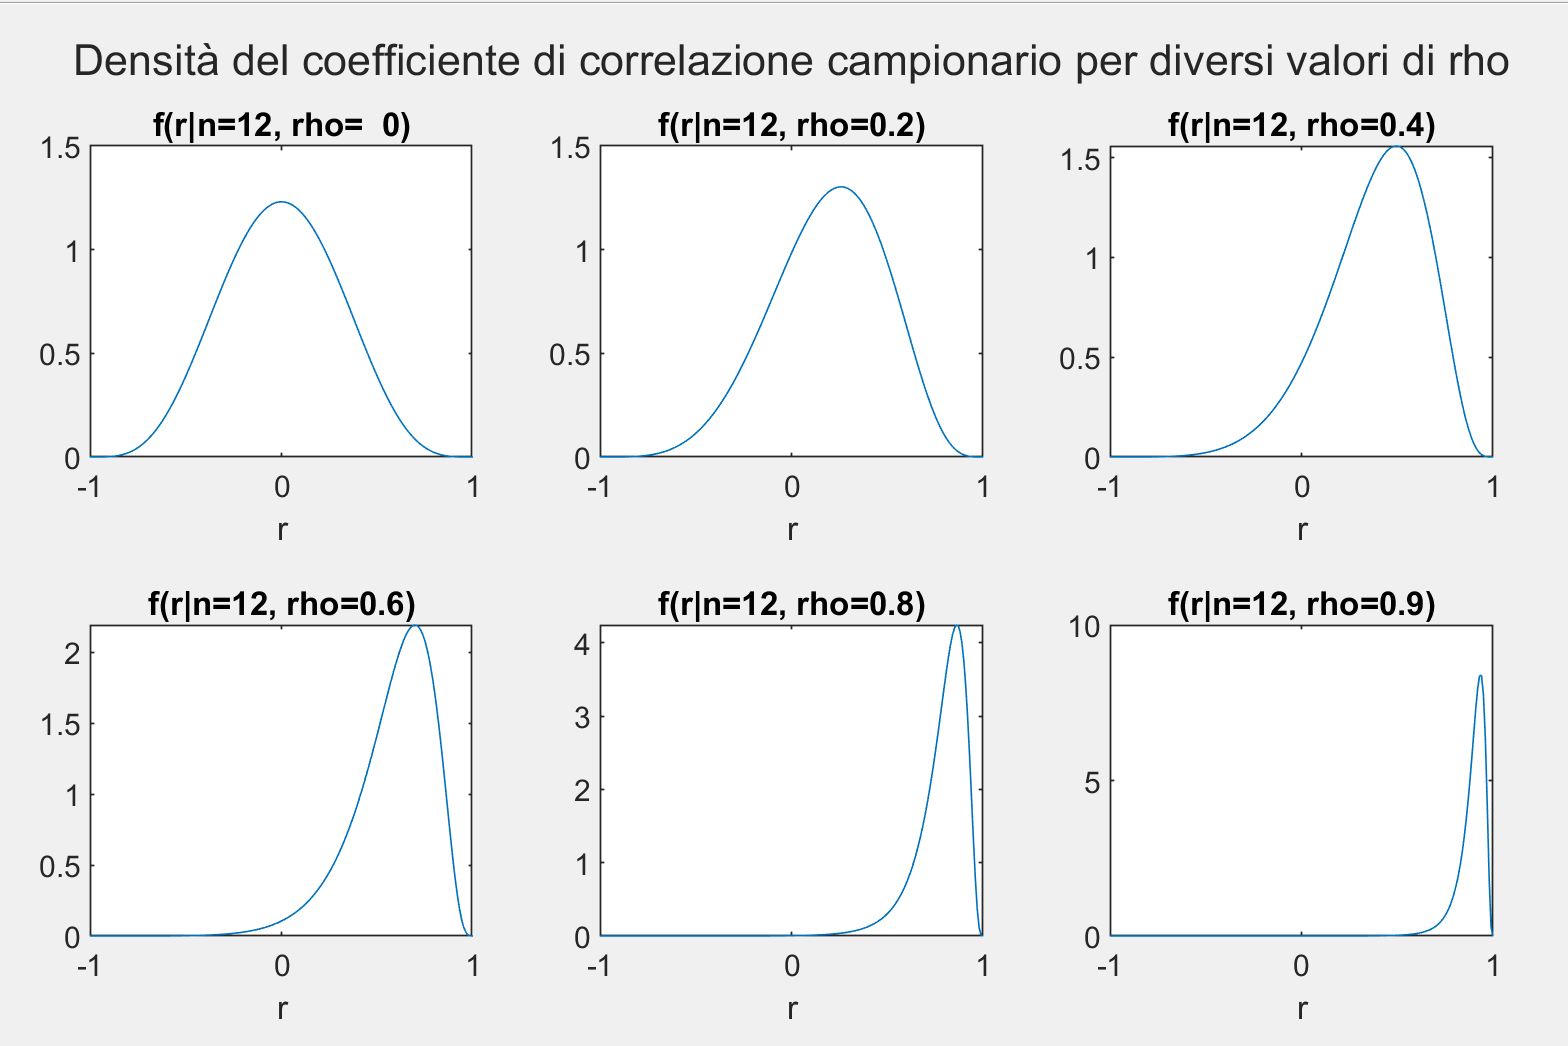

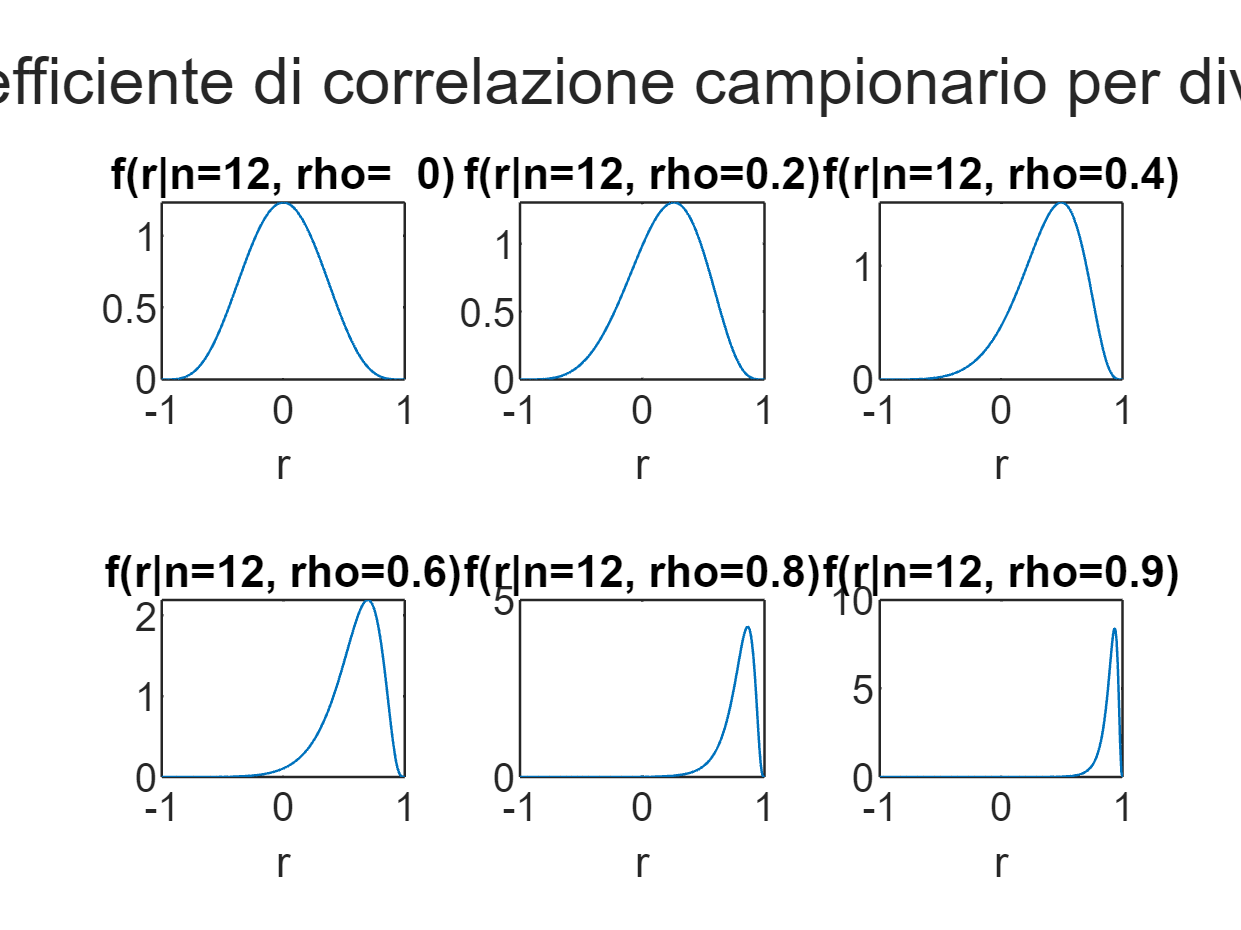

    x=-1:0.01:1;
    rho=[0:0.2:0.8 0.9]';
    n=12;
    rhos=num2str(rho);
    ns=num2str(n);
    close all
    for i=1:length(rho)
        nexttile
        dens=corrpdf(x,rho(i),n);
        plot(x,dens)
        title(['f(r|n=' ns ', rho=' rhos(i,:) ')'])
        xlabel("r")
    end
    
    sgtitle('Densità del coefficiente di correlazione campionario per diversi valori di rho')

## 6) I gradi o ranghi

La matrice di seguito contiene i voti ottenuti nell'esame di matematica generale (MAT), nell'esame di statistica (STAT) e nell'esame di analisi dei dati per il marketing (ADM) di 20 studenti. 

MAT STAT ADM

    21    29    29

    24    23    29

    22    26    28

    28    30    29

    27    27    27

    29    28    28

    29    28    28

    28    27    30

    23    20    23

    21    29    26

    25    27    27

    23    20    22

    28    28    24

    22    19    21

    19    20    19

    18    24    22

    18    22    24

    19    18    28

    29    30    30

    23    26    19

Costruire la matrice dei ranghi.  A ciascuno dei posti a pari merito assegnare un grado uguale alla media aritmetica dei gradi che essi avrebbero avuto se distinguibili.  Costruire la table che contiene i ranghi come mostrato nell'immagine che segue (anteprima output dele prime 8 righe). 

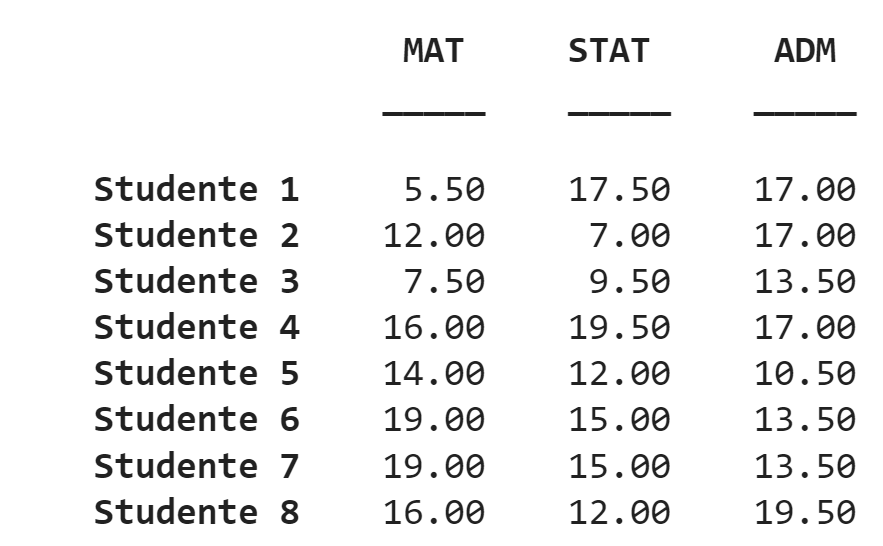

Calcolare la matrice dei coefficienti di cograduazione e verificare la significatività delle relazioni lineari sui gradi (o posti d'ordine). Commentare i p-values della matrice di cograduazione. Verificare l'uguaglianza tra le correlazioni calcolate sui ranghi e i coefficienti di cograduazione calcolati direttamente sulla matrice originaria dei voti.

clear

X= [21    29    29
    24    23    29
    22    26    28
    28    30    29
    27    27    27
    29    28    28
    29    28    28
    28    27    30
    23    20    23
    21    29    26
    25    27    27
    23    20    22
    28    28    24
    22    19    21
    19    20    19
    18    24    22
    18    22    24
    19    18    28
    29    30    30
    23    26    19];
[n,p]=size(X);
% Viene inizializzata la matrice che conterrà i ranghi.
Ranghi=zeros(n,p);
for j=1:p
    Ranghi(:,j)=tiedrank(X(:,j));
end
% Costruzione dei nomi delle righe e delle colonne della table RanghiT che contiene
% i ranghi
nomiRighe="Studente "+(1:n)';
nomiColonne=["MAT" "STAT" "ADM"];
RanghiT=array2table(Ranghi,'RowNames',nomiRighe,'VariableNames',nomiColonne);

disp('Prime 8 righe della table che contiene i ranghi')

Prime 8 righe della table che contiene i ranghi


disp(head(RanghiT))

                   MAT     STAT      ADM 
                  _____    _____    _____

    Studente 1     5.50    17.50    17.00
    Studente 2    12.00     7.00    17.00
    Studente 3     7.50     9.50    13.50
    Studente 4    16.00    19.50    17.00
    Studente 5    14.00    12.00    10.50
    Studente 6    19.00    15.00    13.50
    Studente 7    19.00    15.00    13.50
    Studente 8    16.00    12.00    19.50




% Costruzione delle correlazioni sui ranghi e verifica della loro
% significatività
[R,Pval]=corr(Ranghi);
% Tutti i p-values sono inferiori a 0.05. Al livello di significatività del
% 5 per cento posso rifiutare l'ipotesi nulla di assenza di cograduazione
% tra i voti riportati dagli studenti nei 3 esami. Conclusione: gli
% studenti che prendono voti elevati all'esame di matematica sono
% generalmente quelli che prenderanno voti elevati negli esami di
% statistica e analisi dei dati per il marketing.
[Rchk,Pvalchk]=corr(X,'type','Spearman');

 Rtable=array2table(R,"RowNames",nomiColonne,"VariableNames",nomiColonne);
 disp("Matrice dei coefficienti di cograduazione")

Matrice dei coefficienti di cograduazione


 disp(Rtable)

            MAT     STAT    ADM 
            ____    ____    ____

    MAT     1.00    0.58    0.50
    STAT    0.58    1.00    0.57
    ADM     0.50    0.57    1.00



assert(max(abs(R-Rchk),[],'all')<1e-14,"Le correlazioni sono diverse")
assert(max(abs(Pval-Pvalchk),[],'all')<1e-14,"I p-values sono diversi")